# Lab #2: Probability, Distributions, and Statistical Questions

## Megan Miyasaki 

Partner: Kuan Lee

***Note: kuan here is my draf of lab 1, done and ready for review, pls take your time with it, I know you are busy this weekend. Any changes to my code pls use comment and any changes to my explanation pls make it obvious.  - thank you megan********

## Problem 1

In lecture and homework we explored how the convolution can be used to calculate the probability of a sum or average. For this problem we are going to imagine that we are looking for gamma-ray sources (e.g. with the [Fermi telescope](https://fermi.gsfc.nasa.gov/)). In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray background is some number X (pick someting btwn 0.5 and 10, with different values for you and your lab partner); and the average number of gamma-rays emitted by your hypothetical source is Y (pick something larger than X).

**A) Show how the probability distribution of the background changes as you integrate (sum) for more days.**

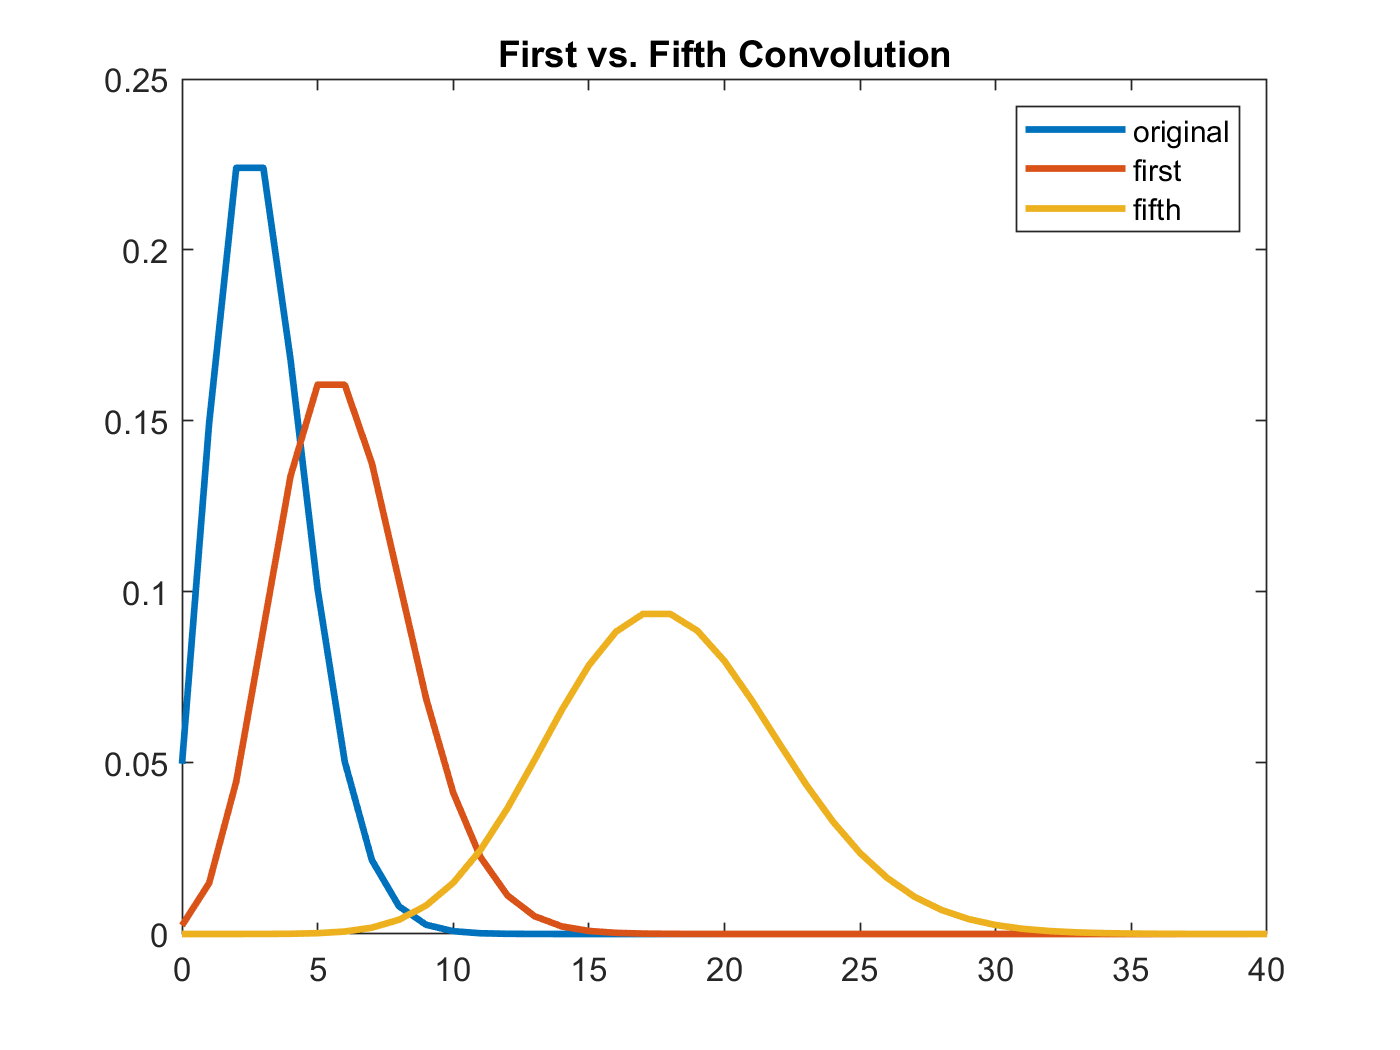

clear;close all;clc;

backgroundX=3; %lambda (background), or avg. cosmic-raybackground
sourceY=9; %labbda (signal), avg. number of gamma-rays emmited by source

% no log
x=0:100;
poisson = makedist("Poisson",'lambda',backgroundX);
prob = pdf(poisson,x);
plot (x, prob, "LineWidth",2) 
hold on

sum1 = conv(prob,prob);
x1=0:200;
plot(x1,sum1,"LineWidth",2)


sum1 = conv(prob,prob);
sum2 = conv(sum1,prob);
sum3 = conv(sum2,prob);
sum4 = conv(sum3,prob);
sum5 = conv(sum4,prob);


sum5 = conv(sum4,prob);
x5=0:600;
plot(x5,sum5,"LineWidth",2)
title('First vs. Fifth Convolution')
xlim([0,40])
legend('original','first','fifth')

hold off

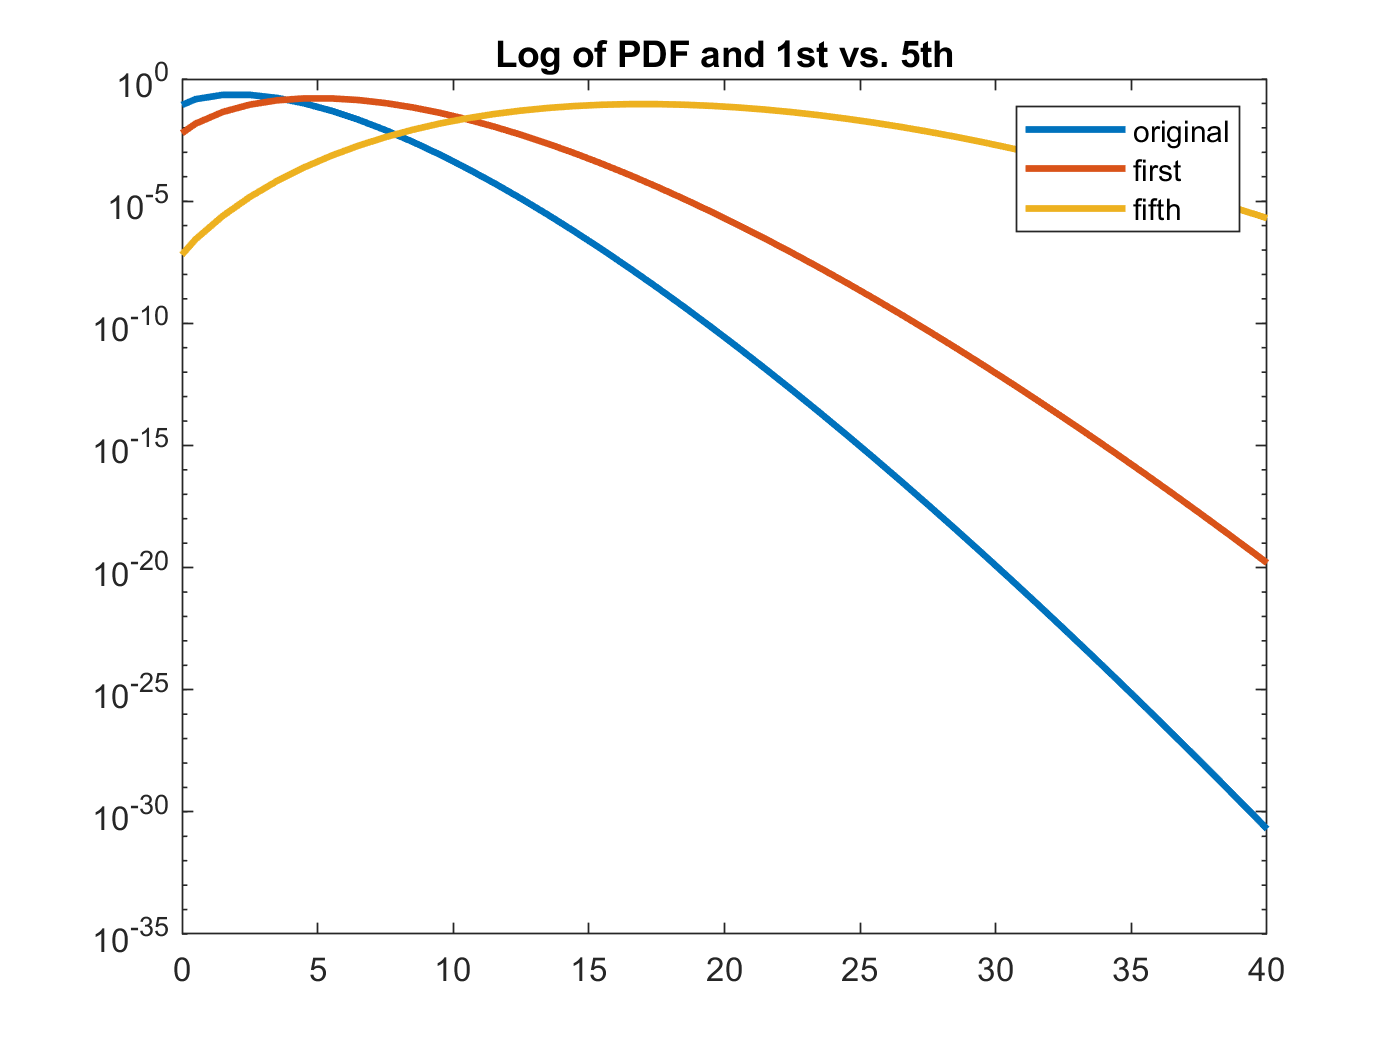

%with log scale
plot (x-0.5, prob, "LineWidth",2)
hold on 
plot(x1-0.5,sum1,"LineWidth",2)
hold on
plot(x5-0.5,sum5,"LineWidth",2)
hold on
title('Log of PDF and 1st vs. 5th')
set(gca,'YScale','log')
legend('original','first','fifth')
xlim([0,40])

hold off 

From the plots we can see that the more days we sum this over of convolute the mean keeps moving out and the distrbution becomes more symmetric. I predict if we keep doing this it could look more like a guassian distribution as proven in lab 1.

**B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.**

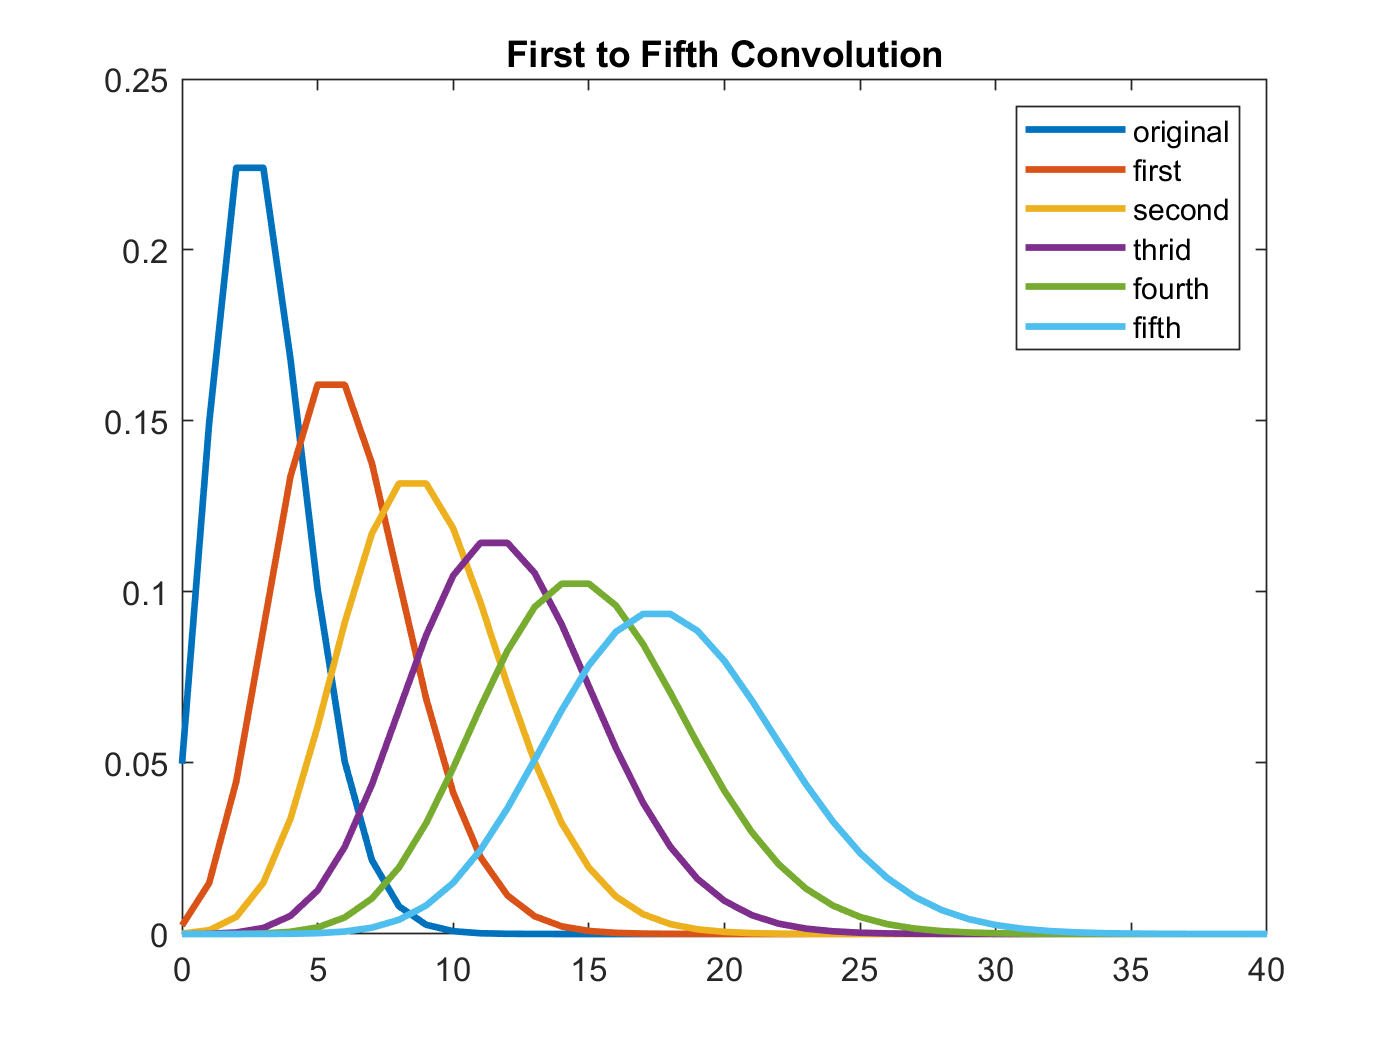

sum1 = conv(prob,prob);
x1=0:200;
sum2 = conv(sum1,prob);
x2=0:300;
sum3 = conv(sum2,prob);
x3=0:400;
sum4 = conv(sum3,prob);
x4=0:500;
sum5 = conv(sum4,prob);
x5=0:600;

% original pdf
x=0:100;
poisson = makedist("Poisson",'lambda',backgroundX);
prob = pdf(poisson,x);
plot (x, prob, "LineWidth",2) %without log scale 
hold on 

%1
plot(x1,sum1,"LineWidth",2)
hold on
%2
plot(x2,sum2,"LineWidth",2)
hold on
%3
plot(x3,sum3,"LineWidth",2)
hold on
%4
plot(x4,sum4,"LineWidth",2)
hold on
%5
plot(x5,sum5,"LineWidth",2)
hold on
title('First to Fifth Convolution')
xlim([0,40])
legend('original','first','second','thrid','fourth','fifth')
hold off

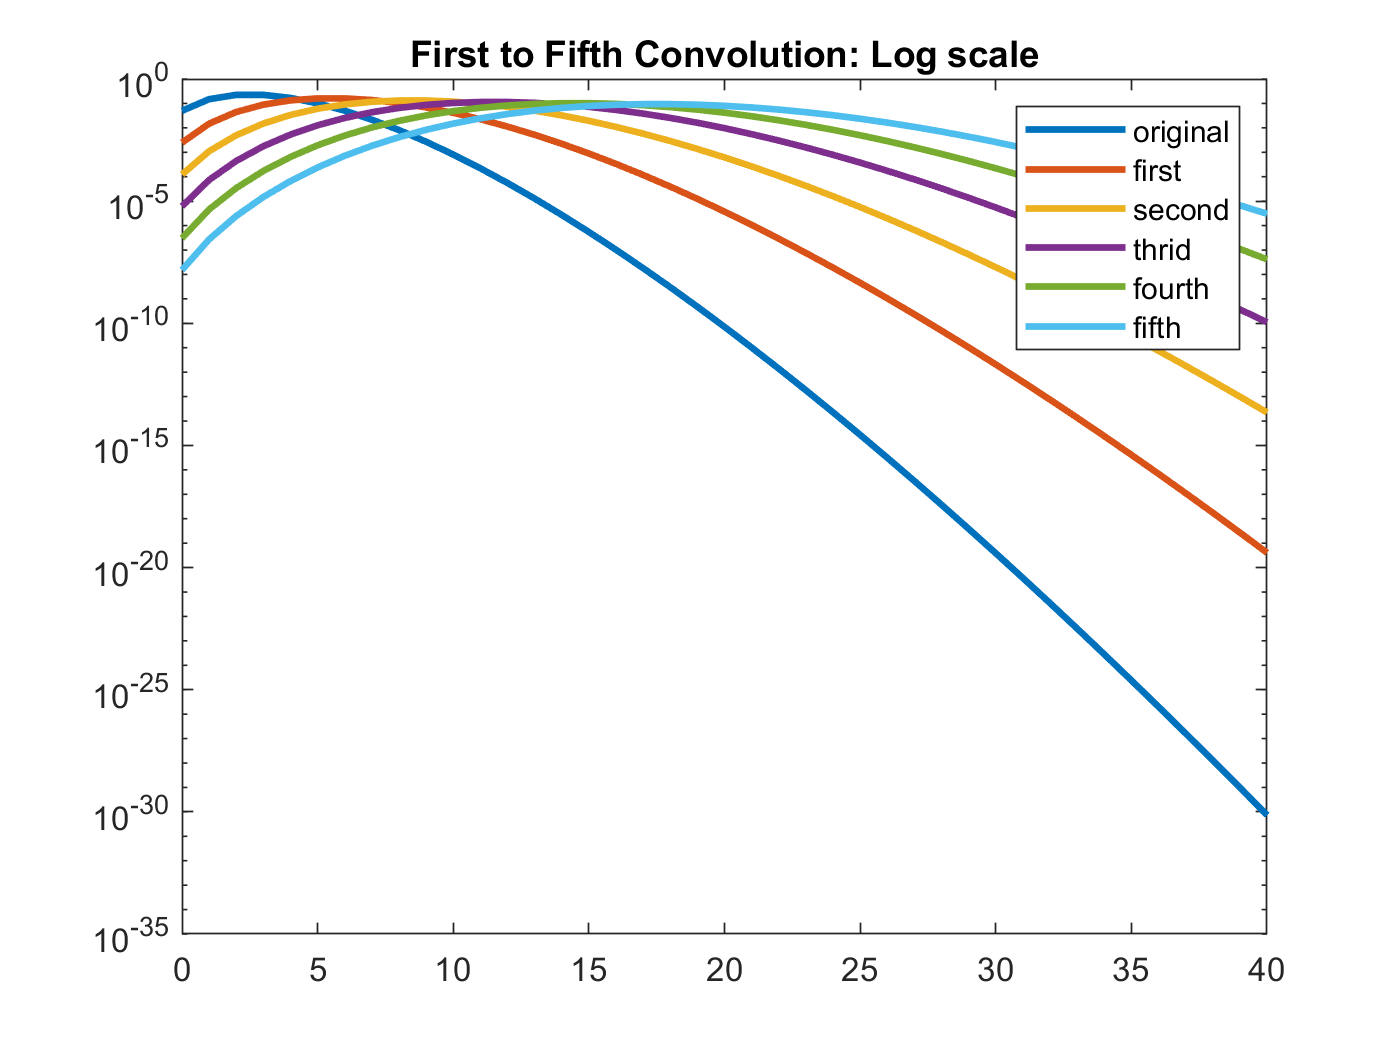


%with log scale
plot (x, prob, "LineWidth",2)
hold on

%1
plot(x1,sum1,"LineWidth",2)

%2
plot(x2,sum2,"LineWidth",2)

%3
plot(x3,sum3,"LineWidth",2)

%4
plot(x4,sum4,"LineWidth",2)

%5
plot(x5,sum5,"LineWidth",2)

set(gca,'YScale','log')
title('First to Fifth Convolution: Log scale')
xlim([0,40])
legend('original','first','second','thrid','fourth','fifth')
hold off

As we can see from the plots, the poission distribution is not changing to much, its the same distribution the only thing that is changing is that the mena is moving out and the plots are looking more symmetric with each convolution. It makes sense that the convolution of a Poisson must be the Possion, just the more you convolute it the more it becomes longer. 

**C) Show how the probability distribution evolves as you *****average***** days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.**

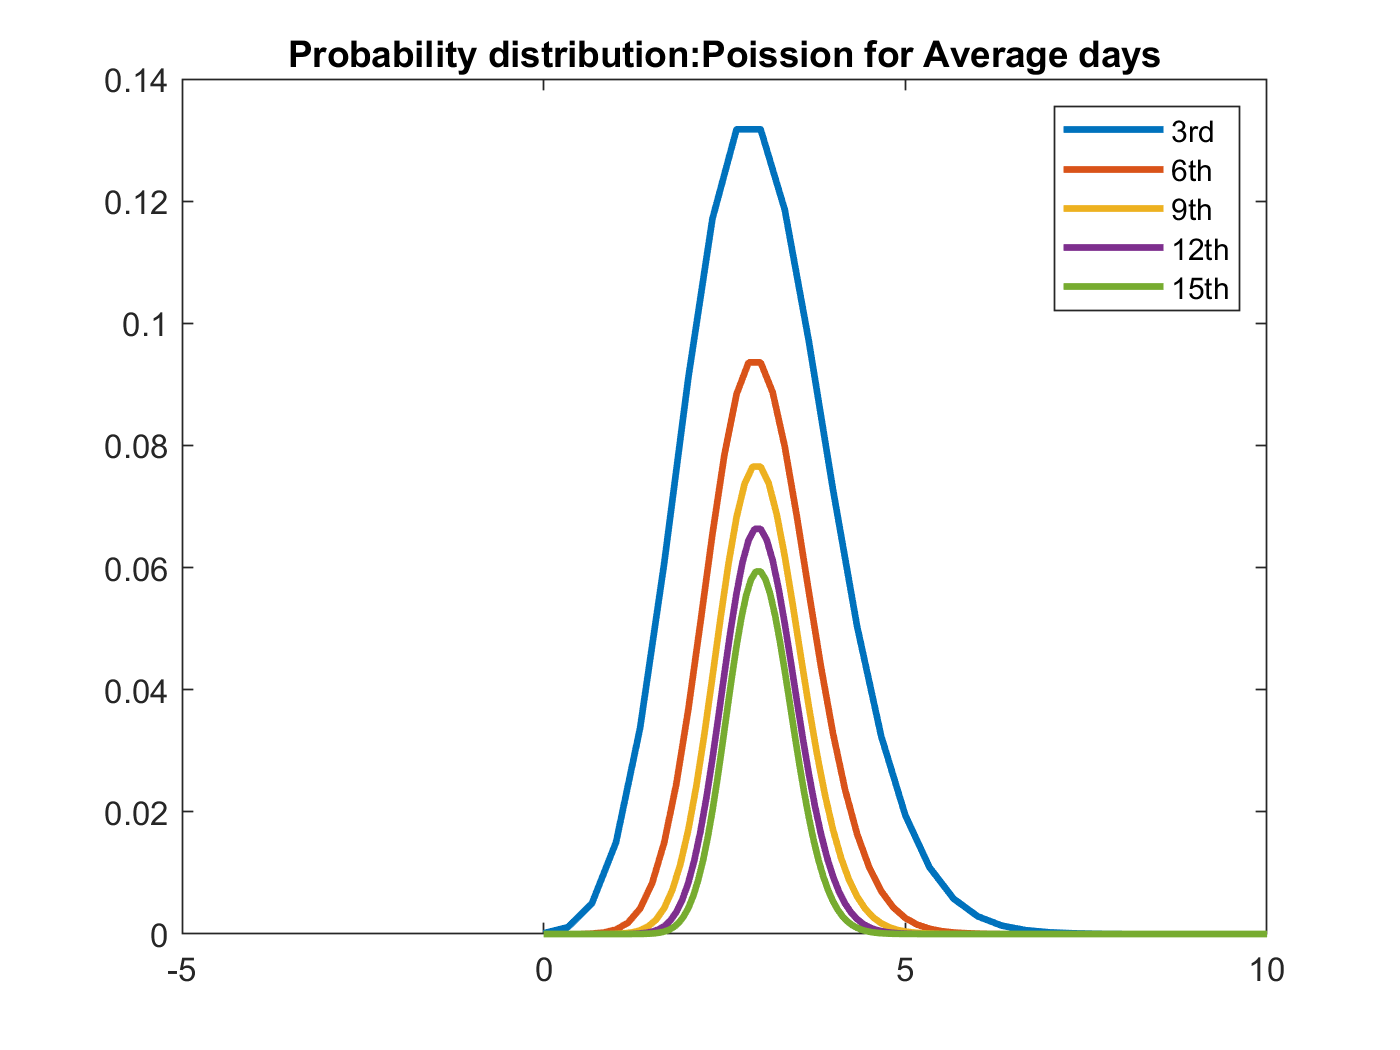

dx=1;
D= [3 6 9 12 15]; 
for k = 1:length(D)
    prev=prob;
    for j = 1:D(k)-1
        sums_d=conv(prev,prob);
        prev=sums_d;
    end
    x_new=min(x):dx/D(k):max(x);
    plot (x_new, prev, "LineWidth",2)
    hold on
end
xlim([-5,10])
title('Probability distribution:Poission for Average days')
legend('3rd','6th','9th','12th','15th')
hold off 

With this chart, I changed the step size with each convolution, so the mean stayed the same, but we can see that they Possion is becoming more Gaussian as the average of days beomes higher. 

**D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]**

N=5; %5days
sourceY=9; %labbda (signal), avg. number of gamma-rays emmited by source

lambda_new=poissfit(sum5); %after convolution of 5 days 
prob_new= 1- cdf(poisson,lambda_new);
sigma=erfc(prob_new);

## Problem 2

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

**A) Show   how the distribution changes as you average over more observing intervals.**

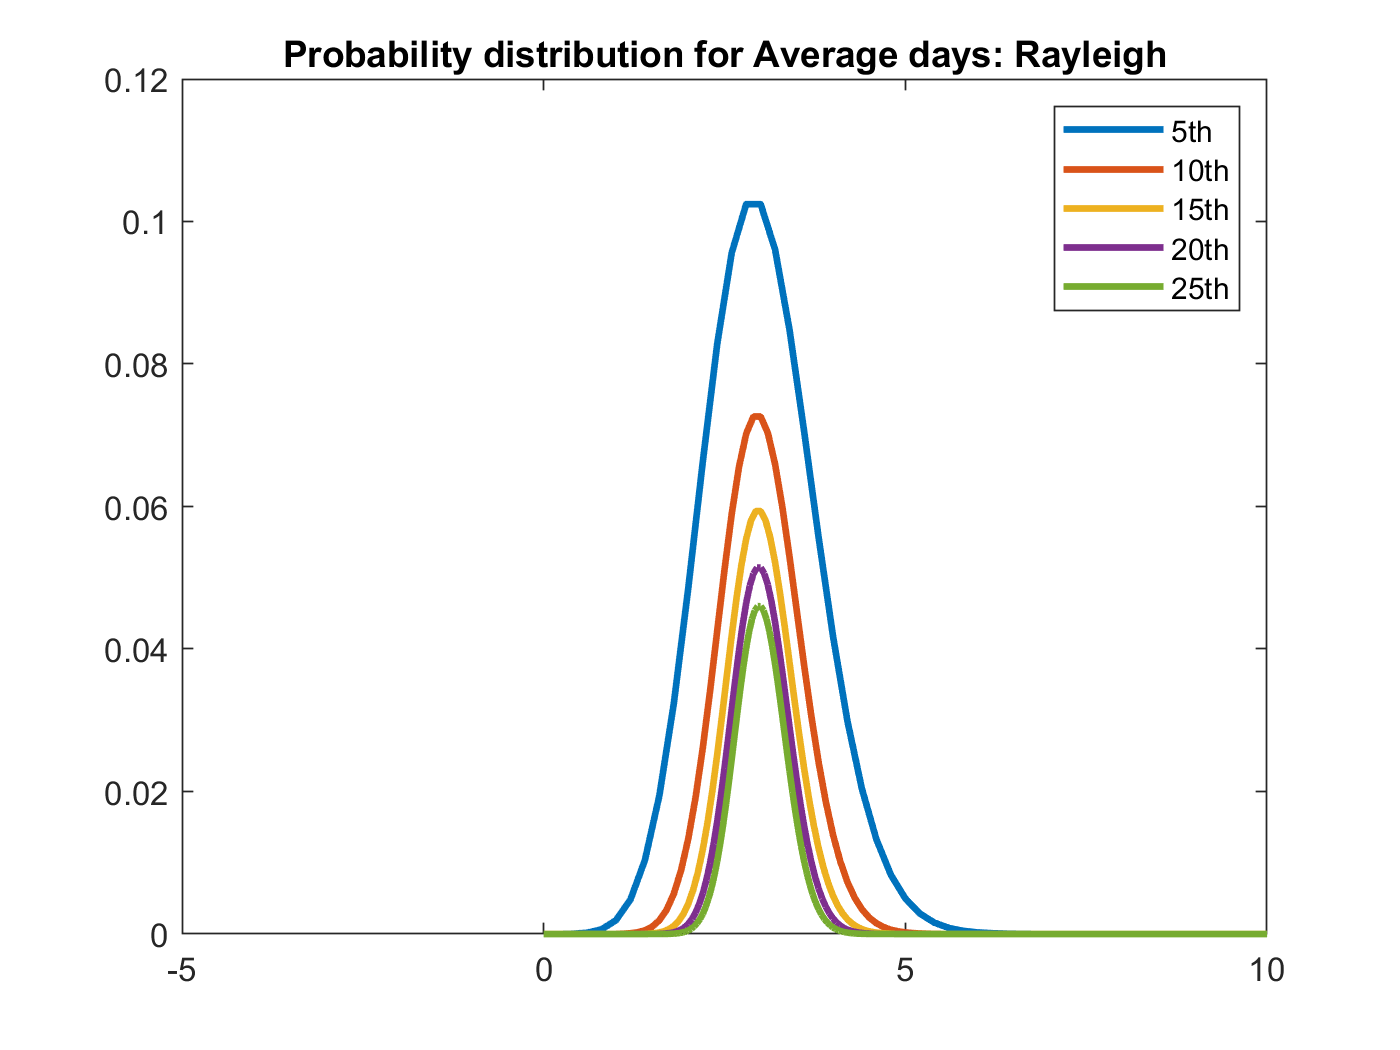

b=1;
x_R=0:100;
Rayleigh = makedist("Rayleigh",'b',b);
prob_R = pdf(Rayleigh,x_R);
dx_R=1;
D_R= [5 10 15 20 25]; 
for k = 1:length(D_R)
    prev=prob;
    for j = 1:D_R(k)-1
        sums_d=conv(prev,prob);
        prev=sums_d;
    end
    x_new=min(x_R):dx_R/D_R(k):max(x_R);
    plot (x_new, prev, "LineWidth",2)
    hold on
end
xlim([-5,10])
title('Probability distribution for Average days: Rayleigh')
legend('5th','10th','15th','20th','25th')
hold off

**B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?**

The shape changes and approaches a gaussian distribution pretty quickly around the 10th convolution, after that it just becomes more and more Gaussian distributed and it can be concluded that if you do enough convolutions the disribution becomes close enough to be treated as a gaussian distribution, which is what the centeral limit theorem, that most distribution when summed or averaged over enough trials, will conver to a gaussian probability distribution function. This one was a pretty quick convergence but it could just be based off the parameters I chose. 

## Problem 3

The discovery of optical/infra-red counterparts of Neutron star mergers initially detected with gravity-waves is one of the great discoverys in the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The science that can be done by matching a gravity-wave signal (directly measures the mass of the neutron stars and their distance) with the optical emisson (redshift, nuclear astrophysics of the resulting explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up when looking for the optical counterparts (a new optical source) of a gravity wave signal. For this problem let's assume that we are using an optical telescope with a thermal noise background from the CCD (dark current, particularly an issue with older CCDs and/or infra-red CCDs). After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

**Version 1**

You have an alert from [LIGO](https://www.ligo.caltech.edu/) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov/). SWIFT gives you a very precise location, so you take an image of that part of the sky. But because of SWIFT's accuracy, you know which pixel in your image to look for a counterpart in.

**A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?**

x_N=0:100;
mu = 0;
sigma = 1 ;
Y = pi ; %floating numbr 
X = makedist("Normal","mu",mu,"sigma",sigma); %vector that contatins guassina distributed values 
prob_N = pdf(X,x_N);
integral=1-normcdf(Y,mu,sigma)

integral = 8.4016e-04

x_sigma = icdf('Normal',integral,0,1)

x_sigma = -3.1416

In order to claim a discovery we need to have a 5-sigma or more, being 1 in 3.5 million. We get sigma to be -3.1416, which is not significant enough to claim the discovery. We integrated over a simple gaussian distribution and still found the result to not be signficant enogh 

**Version 2**

You have an alert from LIGO, but no associated detection from SWIFT. This could be because it is a black hole-black hole merger, a black hole-neutron star merger (neither seem to emit X-rays or UV light), or it could because SWIFT was indisposed at the time (wrong side of the earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

**B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*****Clearly***** state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)**

Statistical Question: If there is no signal from SWIFT then we expect the background to be a Gaussian Distribution, with a mean of 1. The stronger the signal the more events we expect. So what is the probablilty of the background produsing a signal with greater than pi events? 

x_3b=0:10000;
prob_N2=pdf(X,x_3b)*10000;


As we summ the pdf 10k time, the pdf then moves up by a factore of 10k, and it does not convolve, it keeps its shape. 

**C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.**

integralb=1-normcdf(Y,mu,sigma)

integralb = 8.4016e-04

x_sigmab = icdf('Normal',integralb,0,1)/10000

x_sigmab = -3.1416e-04

Specifically for this question the sigma should go down, but not by more than a factor of a few, yet should still remain the same shape. When we  integral the same shape, it remains the same just multiplied. For this distribution, since the pdf fell so quickly, we should not have to move the bounds of integration.

## Problem 4

The statistical issue we were exploring in the previous problem is called a **trials factor** (sometimes known as a look-elsewhere effect). This is an important effect, as if you search through a million locations, the chance of seeing a one in a million event is unity. However, it is also often over estimated how big an impact this makes on the sensitivity of a search. So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

**A) Calculate the signal required for a 5-sigma detection in Version 1**

numpix=10000;
fullrunexp=pdf(X,x)*numpix

fullrunexp = 	1.0e+03 *

    3.9894    2.4197    0.5399    0.0443    0.0013    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0


prob5sigma=1/3.5e6;
detect=icdf(X,1-prob5sigma/numpix)

detect = 6.5510

**B) Calculate the signal required for a 5-sigma detection in Version 2**

numpixb=10000;
fullrunexpb=pdf(X,x)*numpixb

fullrunexpb = 	1.0e+03 *

    3.9894    2.4197    0.5399    0.0443    0.0013    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0


prob5sigma=1/3.5e6;
detect=icdf(X,1-prob5sigma/numpix)

detect = 6.5510

**C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.**

I can only assume that since this is a guassian distribution, the senstive pentaly due to a lot of trails is low, due to the symmetry of the distribution. When you have multiple trials you need abrighter singal because of the sensitivity pentaly. 

**D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?**

In a gaussian distribution if you change the trials factor significanly, the effect on you 5-sigma sensitivity threshold should change proportionally. 

**Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.**

For a gaussian, we have seen that regardless of the number of trail the sensitivity pentaly of many trials will change by a factor about 2-3, so while it affects the sensitivity pentaly by 2-3 times less, than it would to look through a lot of data. With a different shape once can assume it to be a little different because other shapes are not a symmetric as gaussian and it has it own set of rules. If the other distribution on convulated over and over again, then we can use the same logic with Gaussian because most distributions, when summed or averaged over enough trials will conver to a Gaussain pdf. 